S_data = N - I_data - R_data;

dS_data = diff(S_data);
dI_data = diff(I_data);
dR_data = diff(R_data);

%Regresión sobre los datos de logS vs R
w_logSR = polyfit(R_data, log(S_data), 1);

reg_logSR = w_logSR(1)*R_data + w_logSR(2);

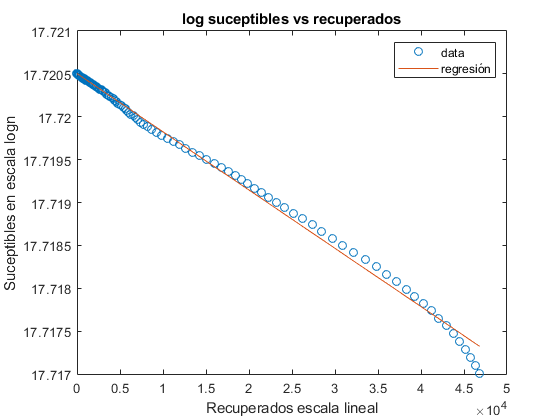

%regresión
figure
plot(R_data, log(S_data), 'o')
hold on
plot(R_data, reg_logSR)
title('log suceptibles vs recuperados')
legend('data', 'regresión')
ylabel('Suceptibles en escala logn')
xlabel('Recuperados escala lineal')

gamma = rmmissing(dR_data./I_data(1:end-1)); 
gamma = 0.09;%sum(gamma)/length(gamma);

beta =0.13;%-N*gamma*w_logSR(1);


%condiciones iniciales
R0 = 0;
S0 = exp(w_logSR(2));
I0 = N - S0;

dates_model =  dates(1):datetime('1-01-2021', 'InputFormat', 'dd-MM-yyyy');
T = 1:length(dates_model);

[T, X] = ode45(@f, T, [S0; I0; R0]);

S = X(:, 1);
I = X(:, 2);
R = X(:, 3);

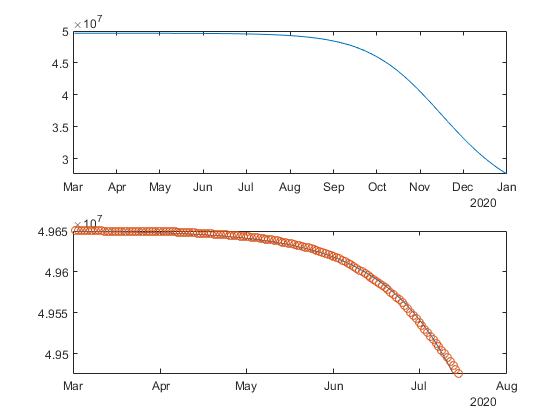

figure
subplot(2, 1, 1)
plot(dates_model, S);
subplot(2, 1, 2)
plot(dates_model, S);
hold on
plot(dates, S_data, 'o');
ylim([min(S_data) max(S_data)])

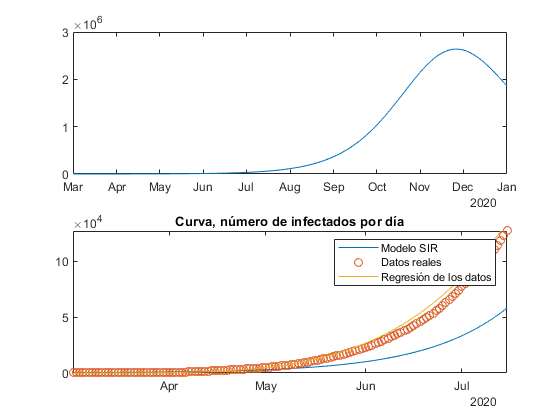

figure('Name', 'Cruvas de Infectados')
subplot(2, 1, 1)
plot(dates_model, I);
subplot(2, 1, 2)
plot(dates_model, I);
hold on
plot(dates, I_data, 'o');
hold on
plot(dates, reg_I);

legend('Modelo SIR', 'Datos reales', 'Regresión de los datos');
title('Curva, número de infectados por día')
ylim([min(I_data) max(I_data)]);
xlim([dates(1) dates(end)])

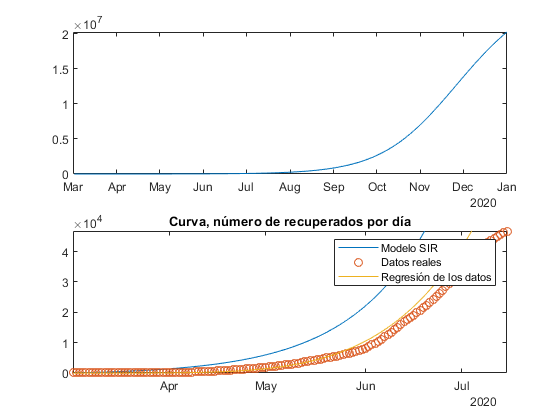

figure
subplot(2, 1, 1)
plot(dates_model, R);
subplot(2, 1, 2)
plot(dates_model, R);
hold on
plot(dates, R_data, 'o');
hold on
plot(dates, reg_R);

legend('Modelo SIR', 'Datos reales', 'Regresión de los datos');
title('Curva, número de recuperados por día')
ylim([min(R_data) max(R_data)]);
xlim([dates(1) dates(end)])

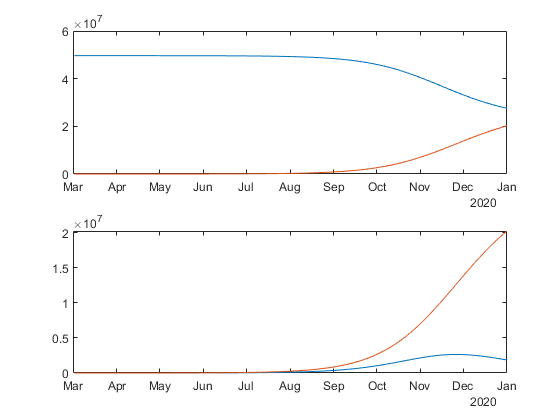


figure
subplot(2, 1, 1)
plot(dates_model, S);
hold on
plot(dates_model, R)
subplot(2, 1, 2)
plot(dates_model, I)
hold on
plot(dates_model, R)

bet = 0:0.01:1;
gam = 0:0.01:1;

err = zeros(length(bet), length(gam));

for i = 1:length(bet)
    for j = 1:length(gam)
        beta = bet(i);
        gamma = gam(j);
        
        [T, Y] = ode45(@f, T, [S0; I0; R0]);
       
        err(i, j) = error(reg_I, Y(:, 2)', t);%(error(reg_I, Y(:, 2)', t) + error(S_data', Y(:, 1)', t) + error(reg_R, Y(:, 3)', t) )/3;
    end
end

minimo_columnas = min(err);
minimo = min(minimo_columnas);

col = find(minimo_columnas == minimo);
fil = find(err(:, col) == minimo);

bet(fil)

ans = 0.7400

gam(col)

ans = 0.6800

function dX = f(t, X)
    S = X(1);
    I = X(2);
    R = X(3);
    gamma = evalin('base', 'gamma');
    beta = evalin('base', 'beta');
    N = evalin('base', 'N');
    
    dX = [-beta*S.*(I/N);...
            beta*S.*(I/N) - gamma*I;...
            gamma*I];

end